clear 
clc

fileID = fopen('data_2024-05-15 13:54:20.316314');
data = fread(fileID,'single') 

data =     0.0044
    0.0044
    0.0044
    0.0044
    0.0045
    0.0044
    0.0044
    0.0044
    0.0044
    0.0045


%data = data/max(data)*10; 
fs = 41.6667e3;
numMics = 8;
onePacketLength = 128*numMics 

onePacketLength = 1024

numPacketsInData = floor(length(data)/onePacketLength)

numPacketsInData = 5120

splitdata = zeros(128,numMics);
for i = 0:numPacketsInData-1
    splitdata = [splitdata; reshape(data(i*onePacketLength+1:(i+1)*onePacketLength),[],numMics)];
end
splitdata = splitdata(128:end,:)'

splitdata =          0   -0.0413   -0.0115    0.0048    0.0075    0.0403    0.0575    0.0283    0.0017   -0.0137   -0.0336   -0.0249    0.0228    0.0420    0.0297    0.0513    0.0794    0.0575    0.0213    0.0138   -0.0027   -0.0202    0.0215    0.0584    0.0386    0.0416    0.0667    0.0316   -0.0206   -0.0128   -0.0115   -0.0420   -0.0295    0.0086    0.0182    0.0176    0.0120   -0.0301   -0.0731   -0.0559   -0.0232   -0.0335   -0.0190    0.0442    0.0510    0.0123    0.0255    0.0497    0.0033   -0.0442
         0   -0.0656   -0.0787   -0.0599   -0.0470   -0.0324   -0.0275   -0.0582   -0.0474   -0.0013    0.0036    0.0036    0.0497    0.0867    0.0529    0.0268    0.0350    0.0221    0.0018   -0.0302   -0.0730   -0.0824   -0.0286    0.0555    0.1018    0.1201    0.1158    0.0653    0.0127   -0.0084   -0.0512   -0.1013   -0.0870   -0.0759   -0.1012   -0.0803   -0.0284   -0.0408   -0.0784   -0.0511   -0.0330   -0.0684   -0.0831   -0.0414    0.0003   -0.0138   -0.0379   -0.0392   -0.0

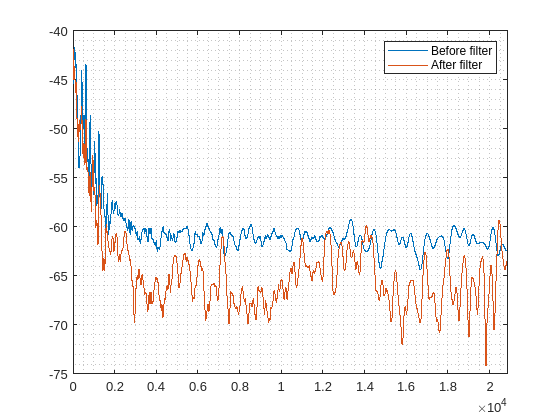


%sound(splitdata(8,:),41e3)

[p_mic0, f_mic0] = pspectrum(splitdata(1,:),fs);
[p_mic1, f_mic1] = pspectrum(splitdata(2,:),fs);
[p_mic2, f_mic2] = pspectrum(splitdata(3,:),fs);
[p_mic3, f_mic3] = pspectrum(splitdata(4,:),fs);
[p_mic4, f_mic4] = pspectrum(splitdata(5,:),fs);
[p_mic5, f_mic5] = pspectrum(splitdata(6,:),fs);
[p_mic6, f_mic6] = pspectrum(splitdata(7,:),fs);
[p_fir, f_fir] = pspectrum(splitdata(8,:),fs);

%plot(f_mic0,10*log10(p_mic0))
%hold on
%plot(f_mic3,10*log10(p_mic3))
%plot(f_mic6,10*log10(p_mic6))
plot(f_mic6,10*log10((p_mic0 + p_mic1 + p_mic2 + p_mic3 + p_mic4 + p_mic5 + p_mic6)*1/7))
hold on
%plot(f_mic0,10*log10(p_mic0))
plot(f_fir,10*log10(p_fir))
legend('Before filter', 'After filter')
%legend('Mic 0', 'Mic 3', 'Mic 6', 'Output of FIR1')
xlim([0 fs/2])
grid minor
hold off